# Indexed Image Visualization

Instructions are in the task pane to the left. Complete and submit each task one at a time. This code creates a 2D surface plot.

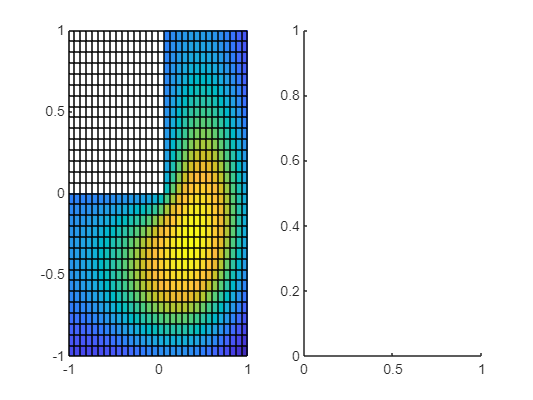

x = linspace(-1,1,31);
y = linspace(-1,1,31);
L = membrane;
L(L==0) = nan(nnz(L==0),1);
axs = subplot(1,2,1);
s = pcolor(x,y,L);
axim = subplot(1,2,2);

## Task 1

**TASK1**

Try to create an indexed image of the data in `L` in the current axes and assign the output to a variable with the name `im`. Specify the x and y ranges so that they span the range of the original `x` and `y` vectors.

**Hint1**

The `imagesc` function displays a scaled color image.

`imagesc``([``xMin` `xMax``]``,``[``yMin` `yMax``]``,``zMatrix``)`

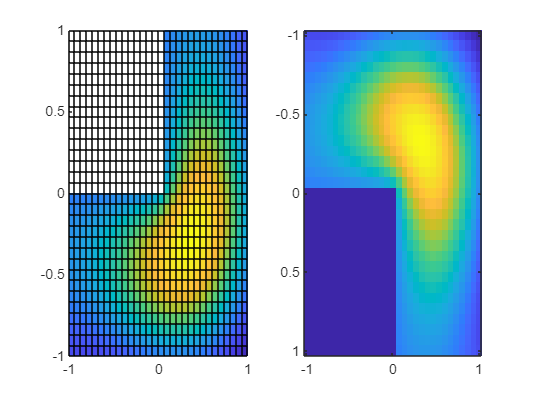

im =   Image with properties:

           CData: [31×31 double]
    CDataMapping: 'scaled'

  Show all properties


im=imagesc([-1 1],[-1 1],L)

## Task 2

Notice the differences between the two images.

Empty, or `NaN`, values are blank in the surface, whereas they are mapped to the minimum value in the image. Also, the alignment of the patch is different. And, the ordering of *y* coordinates is different.

The direction of the *y*-axis can be changed using the `axis` command:

`axis` `xy`

`axis` `ij`

**TASK2**

Modify the direction of the *y*-axis in the image so that it is the same as the surface.

**Hint2**

Use the `axis` `xy` command to have the *y*-axis number from bottom-to-top (mathematical axes).

`axis` `xy`

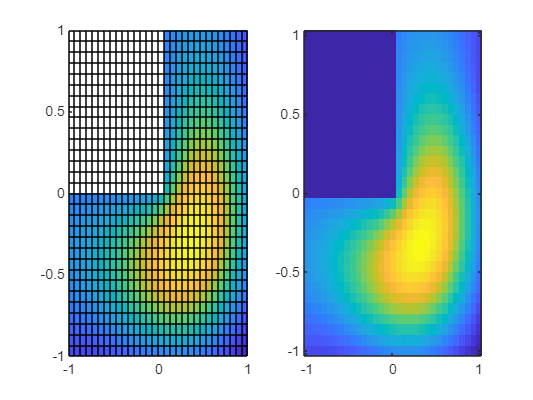

axis xy

## Task 3

**TASK3**

Modify the surface plot by setting the `EdgeColor` to `"none"`.

**Hint3**

Use the `EdgeColor` property of `s`.

`s.EdgeColor` `=` `"interp"`

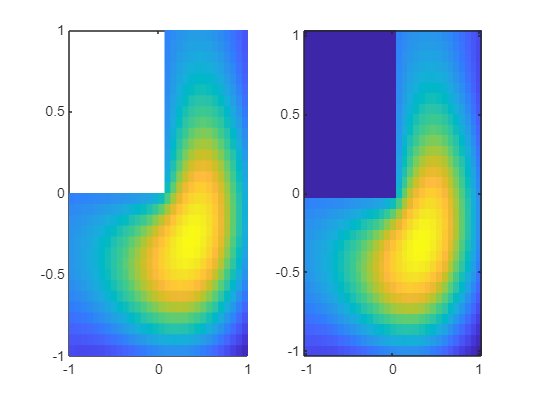

s =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [-1 -0.9333 -0.8667 -0.8000 -0.7333 -0.6667 -0.6000 -0.5333 -0.4667 -0.4000 -0.3333 -0.2667 -0.2000 -0.1333 -0.0667 0 0.0667 0.1333 0.2000 0.2667 0.3333 0.4000 0.4667 0.5333 0.6000 0.6667 0.7333 0.8000 0.8667 0.9333 1]
           YData: [-1 -0.9333 -0.8667 -0.8000 -0.7333 -0.6667 -0.6000 -0.5333 -0.4667 -0.4000 -0.3333 -0.2667 -0.2000 -0.1333 -0.0667 0 0.0667 0.1333 0.2000 0.2667 0.3333 0.4000 0.4667 0.5333 0.6000 0.6667 0.7333 0.8000 0.8667 0.9333 1]
           ZData: [31×31 double]
           CData: [31×31 double]

  Show all properties


s.EdgeColor = "none"